# PIVLab  commandline data analysis workflow

Create a PIVLab options object

pv = pivlab.options("Examples/*.jpeg")

Configure the parallel cluster (optional):

if nr_of_cores > 1
	try
		local_cluster=parcluster('local'); % single node
		corenum =  local_cluster.NumWorkers ; % fix : get the number of cores available
	catch
		warning('on');
		warning('parallel local cluster can not be created, assigning number of cores to 1');
		nr_of_cores = 1;
	end
end

## Create list of images inside user specified directory

directory= [pwd filesep 'Examples'] ; %directory containing the images you want to analyze
% default directory: PIVlab/Examples

suffix='*.jpg'; %*.bmp or *.tif or *.jpg or *.tiff or *.jpeg
disp(['Looking for ' suffix ' files in the selected directory.']);

Looking for *.jpg files in the selected directory.


direc = dir([directory,filesep,suffix]); filenames={};
[filenames{1:length(direc),1}] = deal(direc.name);
filenames = sortrows(filenames); %sort all image files
amount = length(filenames);

## Standard PIV Settings

s = cell(15,2); % To make it more readable, let's create a "settings table"
%Parameter                          %Setting			%Options
s{1,1}= 'Int. area 1';              s{1,2}=64;			% window size of first pass
s{2,1}= 'Step size 1';              s{2,2}=32;			% step of first pass
s{3,1}= 'Subpix. finder';           s{3,2}=1;			% 1 = 3point Gauss, 2 = 2D Gauss
s{4,1}= 'Mask';                     s{4,2}=[];			% If needed, supply a binary image mask with the same size as the PIV images
s{5,1}= 'ROI';                      s{5,2}=[];			% Region of interest: [x,y,width,height] in pixels, may be left empty to process the whole image
s{6,1}= 'Nr. of passes';            s{6,2}=2;			% 1-4 nr. of passes
s{7,1}= 'Int. area 2';              s{7,2}=32;			% second pass window size
s{8,1}= 'Int. area 3';              s{8,2}=16;			% third pass window size
s{9,1}= 'Int. area 4';              s{9,2}=16;			% fourth pass window size
s{10,1}='Window deformation';       s{10,2}='*linear';	% '*spline' is more accurate, but slower
s{11,1}='Repeated Correlation';     s{11,2}=0;			% 0 or 1 : Repeat the correlation four times and multiply the correlation matrices.
s{12,1}='Disable Autocorrelation';  s{12,2}=0;			% 0 or 1 : Disable Autocorrelation in the first pass.
s{13,1}='Correlation style';        s{13,2}=0;			% 0 or 1 : Use circular correlation (0) or linear correlation (1).
s{14,1}='Repeat last pass';			s{14,2}=0;			% 0 or 1 : Repeat the last pass of a multipass analyis
s{15,1}='Last pass quality slope';  s{15,2}=0.025;		% Repetitions of last pass will stop when the average difference to the previous pass is less than this number.

## Standard image preprocessing settings

p = cell(10,1);
%Parameter                       %Setting           %Options
p{1,1}= 'ROI';                   p{1,2}=s{5,2};     % same as in PIV settings
p{2,1}= 'CLAHE';                 p{2,2}=1;          % 1 = enable CLAHE (contrast enhancement), 0 = disable
p{3,1}= 'CLAHE size';            p{3,2}=50;         % CLAHE window size
p{4,1}= 'Highpass';              p{4,2}=0;          % 1 = enable highpass, 0 = disable
p{5,1}= 'Highpass size';         p{5,2}=15;         % highpass size
p{6,1}= 'Clipping';              p{6,2}=0;          % 1 = enable clipping, 0 = disable
p{7,1}= 'Wiener';                p{7,2}=0;          % 1 = enable Wiener2 adaptive denoise filter, 0 = disable
p{8,1}= 'Wiener size';           p{8,2}=3;          % Wiener2 window size
p{9,1}= 'Minimum intensity';     p{9,2}=0.0;        % Minimum intensity of input image (0 = no change)
p{10,1}='Maximum intensity';     p{10,2}=1.0;       % Maximum intensity on input image (1 = no change)

## other settings

pairwise = 1; % 0 for [A+B], [B+C], [C+D]... sequencing style, and 1 for [A+B], [C+D], [E+F]... sequencing style

## PIV analysis loop

if pairwise == 1
	if mod(amount,2) == 1 %Uneven number of images?
		disp('Image folder should contain an even number of images.')
		%remove last image from list
		amount=amount-1;
		filenames(size(filenames,1))=[];
	end

	disp(['Found ' num2str(amount) ' images (' num2str(amount/2) ' image pairs).'])
	x=cell(amount/2,1);
	y=x;
	u=x;
	v=x;
else
	disp(['Found ' num2str(amount) ' images'])
	x=cell(amount-1,1);
	y=x;
	u=x;
	v=x;
end

Found 20 images (10 image pairs).



typevector=x; %typevector will be 1 for regular vectors, 0 for masked areas
correlation_map=x; % correlation coefficient

## Pre-load the image names out side of the parallelizable loop

slicedfilename1=cell(0);
slicedfilename2=cell(0);
j = 1;
for i=1:1+pairwise:amount-1
	slicedfilename1{j}=filenames{i}; % begin
	slicedfilename2{j}=filenames{i+1}; % end
	j = j+1;
end

## Main PIV analysis loop:

Parallel processing or...

if nr_of_cores > 1
	if pivparpool('size')<nr_of_cores
		pivparpool('open',nr_of_cores);
	end

	parfor i=1:size(slicedfilename1,2)  % index must increment by 1

		[x{i}, y{i}, u{i}, v{i}, typevector{i},correlation_map{i}] = ...
			piv_analysis(directory, slicedfilename1{i}, slicedfilename2{i},p,s,nr_of_cores,false);
	end

... Sequential loop

10 %
15 %
20 %
25 %
30 %
35 %
40 %
45 %
50 %


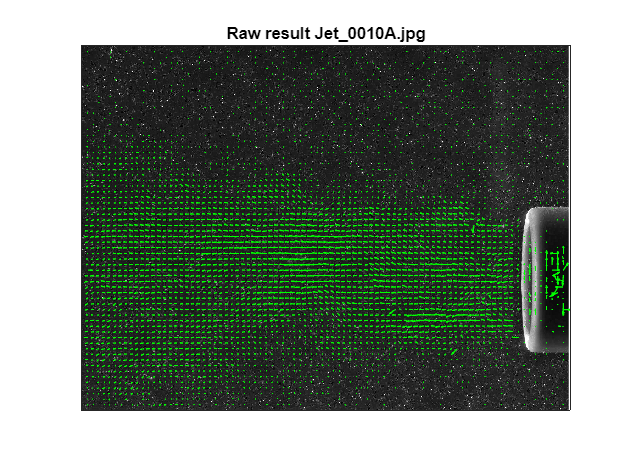

55 %


else % sequential loop

	for i=1:size(slicedfilename1,2)  % index must increment by 1

		[x{i}, y{i}, u{i}, v{i}, typevector{i},correlation_map{i}] = ...
			piv_analysis(directory, slicedfilename1{i}, slicedfilename2{i},p,s,nr_of_cores,true);

		disp([int2str((i+1)/amount*100) ' %']);

	end
end

The most important results are x,y,u,v. These can now be viewed before validation:

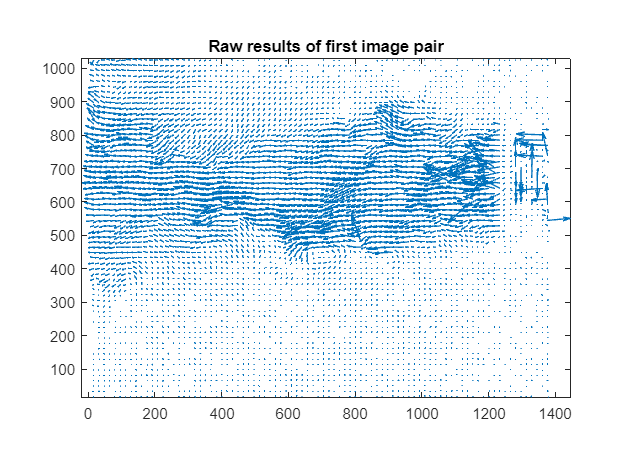

figure;quiver(x{1},y{1},u{1},v{1},5);axis image;  %(the last number determines the displayed sclae of the vectors)
title('Raw results of first image pair')

## PIV postprocessing loop

Standard image post processing settings

r = cell(6,1);
%Parameter     %Setting                                     %Options
r{1,1}= 'Calibration factor, 1 for uncalibrated data';      r{1,2}=1;                   % Calibration factor for u
r{2,1}= 'Calibration factor, 1 for uncalibrated data';      r{2,2}=1;                   % Calibration factor for v
r{3,1}= 'Valid velocities [u_min; u_max; v_min; v_max]';    r{3,2}=[-50; 50; -50; 50];  % Maximum allowed velocities, for uncalibrated data: maximum displacement in pixels
r{4,1}= 'Stdev check?';                                     r{4,2}=1;                   % 1 = enable global standard deviation test
r{5,1}= 'Stdev threshold';                                  r{5,2}=7;                   % Threshold for the stdev test
r{6,1}= 'Local median check?';                              r{6,2}=1;                   % 1 = enable local median test
r{7,1}= 'Local median threshold';                           r{7,2}=3;                   % Threshold for the local median test

u_filt=cell(size(u));
v_filt=cell(size(v));
typevector_filt=typevector;

if nr_of_cores >1 % parallel loop

	if pivparpool('size')<nr_of_cores
		pivparpool('open',nr_of_cores);
	end

	parfor PIVresult=1:size(x,1)

		[u_filt{PIVresult,1}, v_filt{PIVresult,1},typevector_filt{PIVresult,1}]= ...
			post_proc_wrapper(u{PIVresult,1},v{PIVresult,1},typevector{PIVresult,1},r,true);

	end

else % sequential loop

	for PIVresult=1:size(x,1)

		[u_filt{PIVresult,1}, v_filt{PIVresult,1},typevector_filt{PIVresult,1}]= ...
			post_proc_wrapper(u{PIVresult,1},v{PIVresult,1},typevector{PIVresult,1},r,true);

	end

end

Post-processing finished, here are the filtered results:

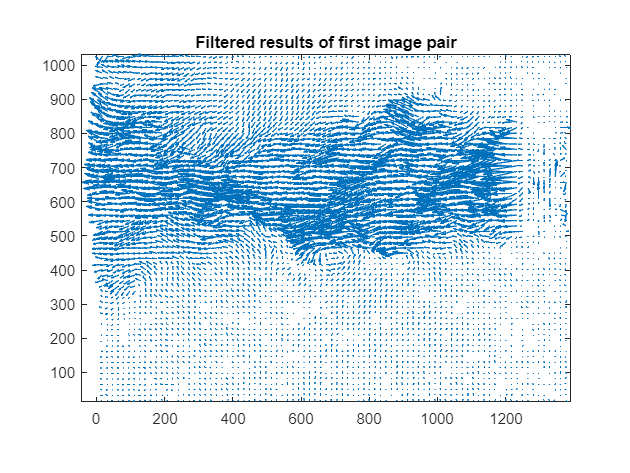

figure;quiver(x{1},y{1},u_filt{1},v_filt{1},5);axis image; %(the last number determines the displayed sclae of the vectors)
title('Filtered results of first image pair')

## clean up parallel pool, and cluster (if required, will save RAM)

%{
if nr_of_cores >1 % parallel
	poolobj = gcp('nocreate'); % GET the current parallel pool
	if ~isempty(poolobj ); delete(poolobj );end
	clear local_cluster;
end
%}

Save the data to a Matlab file

save(fullfile(directory, [filenames{1} '_' filenames{end} '_' num2str(amount) '_frames_result_.mat']));

Clean up unused vars

clearvars -except p s r x y u v typevector directory filenames u_filt v_filt typevector_filt correlation_map
disp('DONE.')

DONE.


Wrapper function for PIVlab_postproc

function [u_filt, v_filt,typevector_filt] = post_proc_wrapper(u,v,typevector,post_proc_setting,paint_nan)
% wrapper function for PIVlab_postproc

% INPUT
% u, v: u and v components of vector fields
% typevector: type vector
% post_proc_setting: post processing setting
% paint_nan: bool, whether to interpolate missing data

% OUTPUT
% u_filt, v_filt: post-processed u and v components of vector fields
% typevector_filt: post-processed type vector


[u_filt,v_filt] = PIVlab_postproc(u,v, ...
	post_proc_setting{1,2},...
	post_proc_setting{2,2},...
	post_proc_setting{3,2},...
	post_proc_setting{4,2},...
	post_proc_setting{5,2},...
	post_proc_setting{6,2},...
	post_proc_setting{7,2});

typevector_filt = typevector; % initiate
typevector_filt(isnan(u_filt))=2;
typevector_filt(isnan(v_filt))=2;
typevector_filt(typevector==0)=0; %restores typevector for mask

if paint_nan
	u_filt=inpaint_nans(u_filt,4);
	v_filt=inpaint_nans(v_filt,4);
end


end